clear, clc, format short g 

data = importdata("dati_punto_1.mat")

data = struct with fields:
          C: 1.5e-08
      H_dot: [1×1 tf]
          N: 1000
         Np: 3
          R: 74.38
       Rgen: 50
         Td: 0.00013528
         Ts: 1.3528e-07
         Tx: 4.5093e-05
        Vpp: 10
         fx: 22176
          n: [1000×1 double]
      sigma: 0.2
          t: [1000×1 double]
    tau_sin: 1.1157e-06
      x_sin: [1000×1 double]
      y_sin: [1000×1 double]


C = data.C;
R = data.R;
Rgen = data.Rgen;
H_dot = data.H_dot;
tau_sin = data.tau_sin;
Vpp = data.Vpp;
sigma = data.sigma;
N = data.N;
Np = data.Np;
n = data.n;
Tx = data.Tx;
Ts = data.Ts;
Td = data.Td;
t = data.t;
fx = data.fx;

x_sin = data.x_sin;
y_sin = data.y_sin;


## PARTE 2

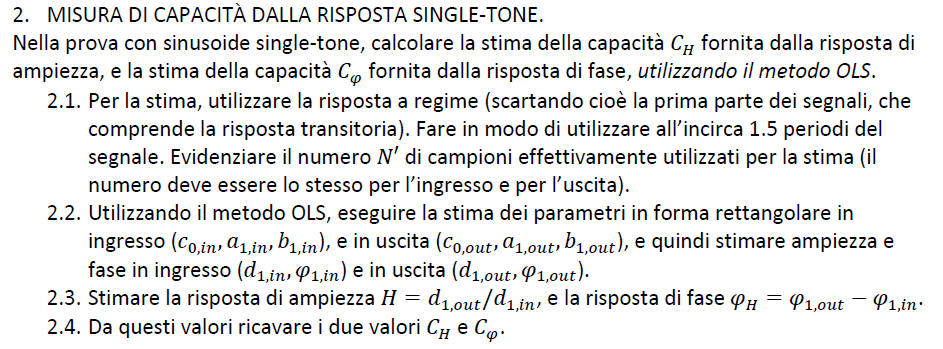

N2 = length(t)/2 % numero di campioni della risposta a regime

N2 =    500



t1 = (N2+1:N)' %vettore dei tempi contenenti gli istanti a regime

t1 =    501
   502
   503
   504
   505
   506
   507
   508
   509
   510


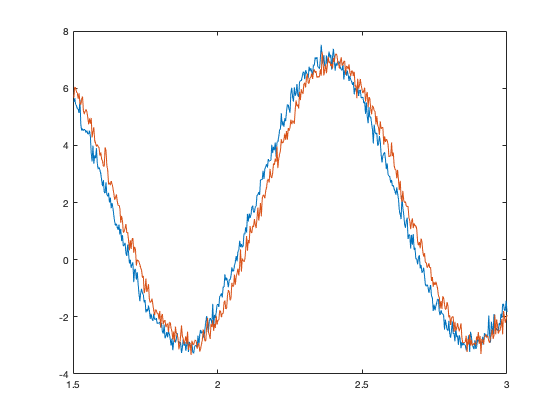

rng('default') % resetto il motore random

Fx = Np/N; %frequenza digitale

x_sin = 2 + Vpp/2*cos(2*pi*n*Fx - pi/4 - pi/2) + randn(N,1)*sigma; %trasformo seni in coseni per poter successivamente applicare il metodo OLS lineare
y_sin = lsim(H_dot, x_sin, t) + randn(N,1)*sigma;


xs = x_sin(N2+1:N); %segnale in ingresso ristretto agli ultimi campioni
ys = y_sin(N2+1:N); %segnale in uscita ristretto agli ultimi campioni


plot(t1*Fx, xs, t1*Fx, ys)


a1 = Vpp*cos(-3*pi/4); % coefficienti rettangolari
b1 = Vpp*sin(-3*pi/4);

wt = 2*pi*Fx*t1; % argomento delle funzioni base


A = [ones(N2,1), cos(wt), -sin(wt)]; % matrice delle funzioni base


## Stima dei parametri di input

theta_hat_x = inv(A'*A)*A'*xs; % A\y

%estrazione della stima dei coefficienti della forma rettangolare in
%ingresso

c0_hat_x = theta_hat_x(1);
a1_hat_x = theta_hat_x(2);
b1_hat_x = theta_hat_x(3);

%stima dei coefficienti della forma polare in ingresso

d1_hat_x = sqrt(a1_hat_x^2 + b1_hat_x^2);

phi1_hat_x = atan2(b1_hat_x, a1_hat_x);


## Stima dei parametri di output

theta_hat_y = inv(A'*A)*A'*ys; % forma alternativa A\y

%estrazione della stima dei coefficienti della forma rettangolare in uscita
c0_hat_y = theta_hat_y(1);
a1_hat_y = theta_hat_y(2);
b1_hat_y = theta_hat_y(3);

%stima dei coefficienti della forma polare in uscita

d1_hat_y = sqrt(a1_hat_y^2 + b1_hat_y^2);

phi1_hat_y = atan2(b1_hat_y, a1_hat_y);;


## Organizziamo i dati in una Tabella

rows = [{'INPUT'},{'OUTPUT'}];
c0=[c0_hat_x;c0_hat_y];
a1=[a1_hat_x;a1_hat_y];
b1=[b1_hat_x;b1_hat_y];
d1=[d1_hat_x;d1_hat_y];
phi=[phi1_hat_x;phi1_hat_y];
T = table(c0,a1,b1,d1,phi,'RowNames',rows)

T = 2×5 table
                c0        a1         b1         d1        phi  
              ______    _______    _______    ______    _______

    INPUT     1.9871    -3.5868    -3.4483    4.9755    -2.3759
    OUTPUT      1.99    -4.0172    -2.8246    4.9108    -2.5288


## Stima risposta di ampiezza e di fase


H = d1_hat_y/d1_hat_x

H =         0.987



phi = phi1_hat_y - phi1_hat_x

phi =      -0.15289


## Ricaviamo C_H e C_phi


C_H = (sqrt(1-(H^2)/H)*(1/(2*pi*fx*R)))

C_H =    1.1001e-08



C_phi = tan(-phi)*(1/(2*pi*fx*R))

C_phi =    1.4868e-08



save dati_punto_2 C_H C_phi xs ys c0_hat_x c0_hat_y a1_hat_y a1_hat_x b1_hat_y b1_hat_x H phi d1_hat_y d1_hat_x phi1_hat_y phi1_hat_x A theta_hat_x theta_hat_y N R fx